Colin Keenan

ECE 5470

3-1-2020

# Homework 5

1.  Fourier Spectrum and Average Value

## Compute, Center, and Enhance Fourier Spectrum for Fig5-1a.jpg, Fig5-1b.jpg, Fig5-1c.jpg, and Fig5-1d.jpg

clear

fprintf("Question 1:")

Question 1:

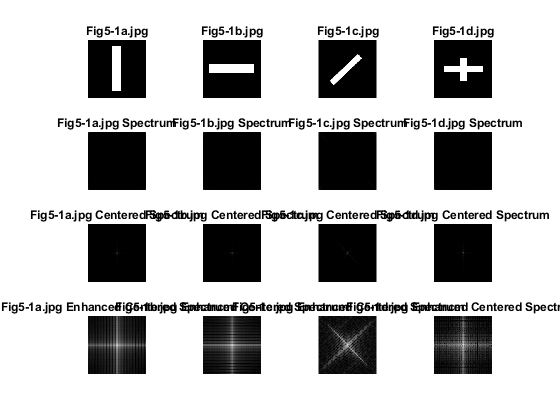


imageA = imread('Fig5-1a.jpg');
imageB = imread('Fig5-1b.jpg');
imageC = imread('Fig5-1c.jpg');
imageD = imread('Fig5-1d.jpg');

[AS, AcS, AeS] = cceFourierSpec(imageA);
[BS, BcS, BeS] = cceFourierSpec(imageB);
[CS, CcS, CeS] = cceFourierSpec(imageC);
[DS, DcS, DeS] = cceFourierSpec(imageD);

figure();
% Original Images
subplot(4,4,1)
imshow(imageA);
title("Fig5-1a.jpg");
subplot(4,4,2)
imshow(imageB);
title("Fig5-1b.jpg");
subplot(4,4,3)
imshow(imageC);
title("Fig5-1c.jpg");
subplot(4,4,4)
imshow(imageD);
title("Fig5-1d.jpg");

% Fourier Spectrums
subplot(4,4,5)
imshow(AS, []);
title("Fig5-1a.jpg Spectrum");
subplot(4,4,6)
imshow(BS, []);
title("Fig5-1b.jpg Spectrum");
subplot(4,4,7)
imshow(CS, []);
title("Fig5-1c.jpg Spectrum");
subplot(4,4,8)
imshow(DS, []);
title("Fig5-1d.jpg Spectrum");

% Centered Fourier Spectrums
subplot(4,4,9)
imshow(AcS, []);
title("Fig5-1a.jpg Centered Spectrum");
subplot(4,4,10)
imshow(BcS, []);
title("Fig5-1b.jpg Centered Spectrum");
subplot(4,4,11)
imshow(CcS, []);
title("Fig5-1c.jpg Centered Spectrum");
subplot(4,4,12)
imshow(DcS, []);
title("Fig5-1d.jpg Centered Spectrum");

% Enhanced Centered Spectrums
subplot(4,4,13)
imshow(AeS, []);
title("Fig5-1a.jpg Enhanced Centered Spectrum");
subplot(4,4,14)
imshow(BeS, []);
title("Fig5-1b.jpg Enhanced Centered Spectrum");
subplot(4,4,15)
imshow(CeS, []);
title("Fig5-1c.jpg Enhanced Centered Spectrum");
subplot(4,4,16)
imshow(DeS, []);
title("Fig5-1d.jpg Enhanced Centered Spectrum");

2. Ideal Low-Pass Filtering

## Apply an Ideal Low Pass Filter to Fig5-2a.jpg and Fig5-2b.jpg with D0 values of 20 and 60

clear

fprintf("Question 2:")

Question 2:

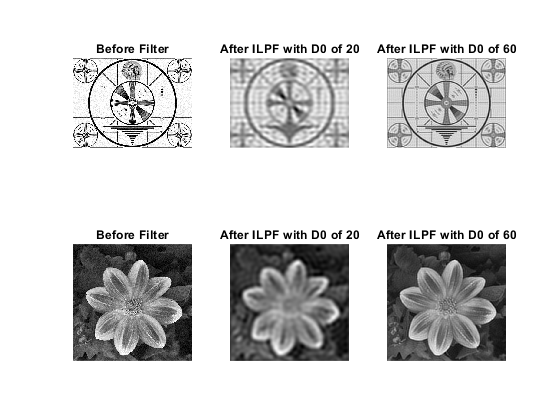


imageA = imread('Fig5-2a.jpg');
imageB = imread('Fig5-2b.jpg');

Ailpf20 = ilpf(imageA, 20);
Ailpf60 = ilpf(imageA, 60);
Bilpf20 = ilpf(imageB, 20);
Bilpf60 = ilpf(imageB, 60);

figure();
% Fig5-2a.jpg
subplot(2,3,1)
imshow(imageA);
title("Before Filter");
subplot(2,3,2)
imshow(Ailpf20, []);
title("After ILPF with D0 of 20");
subplot(2,3,3)
imshow(Ailpf60, []);
title("After ILPF with D0 of 60");
% Fig5-2b.jpg
subplot(2,3,4)
imshow(imageB);
title("Before Filter");
subplot(2,3,5)
imshow(Bilpf20, []);
title("After ILPF with D0 of 20");
subplot(2,3,6)
imshow(Bilpf60, []);
title("After ILPF with D0 of 60");

Explanation: The above code filters the images using a ideal low-pass filter which does smooth out the image, however there is an odd halo-like artifacting on big changes between light and dark.

3. Butterworth Low-Pass Filtering

## Apply an Butterworth Low Pass Filter to Fig5-2a.jpg and Fig5-2b.jpg with D0 values of 20 and 60

clear

fprintf("Question 3:")

Question 3:

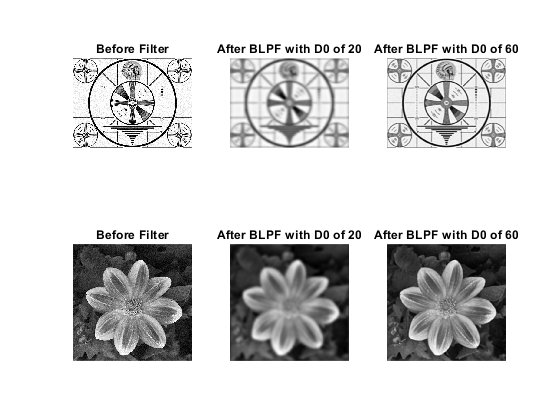


imageA = imread('Fig5-2a.jpg');
imageB = imread('Fig5-2b.jpg');

Ablpf20 = blpf(imageA, 20);
Ablpf60 = blpf(imageA, 60);
Bblpf20 = blpf(imageB, 20);
Bblpf60 = blpf(imageB, 60);

figure();
% Fig5-2a.jpg
subplot(2,3,1)
imshow(imageA);
title("Before Filter");
subplot(2,3,2)
imshow(Ablpf20, []);
title("After BLPF with D0 of 20");
subplot(2,3,3)
imshow(Ablpf60, []);
title("After BLPF with D0 of 60");
% Fig5-2b.jpg
subplot(2,3,4)
imshow(imageB);
title("Before Filter");
subplot(2,3,5)
imshow(Bblpf20, []);
title("After BLPF with D0 of 20");
subplot(2,3,6)
imshow(Bblpf60, []);
title("After BLPF with D0 of 60");

Explanation: The above code filters the images using a butterworth low-pass filter, which when compared with the previous ideal filter is much better at showing a smooth transition between dark and light without the odd halo-artifacting seen with the ideal filter.

4.  Gaussian Low-Pass Filtering

## Apply an Gaussian Low Pass Filter to Fig5-2a.jpg and Fig5-2b.jpg with D0 values of 20 and 60

clear

fprintf("Question 4:")

Question 4:

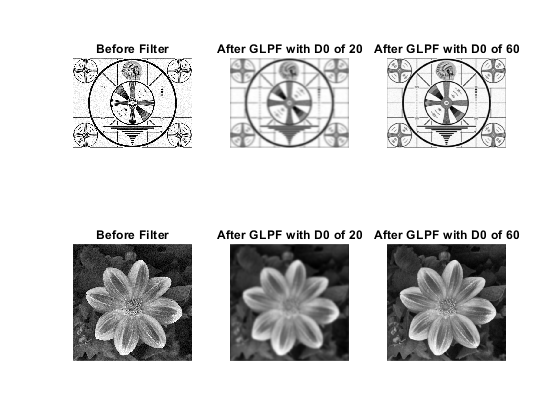


imageA = imread('Fig5-2a.jpg');
imageB = imread('Fig5-2b.jpg');

Aglpf20 = glpf(imageA, 20);
Aglpf60 = glpf(imageA, 60);
Bglpf20 = glpf(imageB, 20);
Bglpf60 = glpf(imageB, 60);

figure();
% Fig5-2a.jpg
subplot(2,3,1)
imshow(imageA);
title("Before Filter");
subplot(2,3,2)
imshow(Aglpf20, []);
title("After GLPF with D0 of 20");
subplot(2,3,3)
imshow(Aglpf60, []);
title("After GLPF with D0 of 60");
% Fig5-2b.jpg
subplot(2,3,4)
imshow(imageB);
title("Before Filter");
subplot(2,3,5)
imshow(Bglpf20, []);
title("After GLPF with D0 of 20");
subplot(2,3,6)
imshow(Bglpf60, []);
title("After GLPF with D0 of 60");

Explanation: The above code filters the images using a gaussian low-pass filter, which when compared with the previous two filters has the smoothest transitions between intensities.

## Appendix (Functions Used)

function [S,cS,eS] = cceFourierSpec(imag)
% Description: Compute, Center, and Enhance a Fourier Spectrum of an Image

% Base FFT
F = fft2(im2double(imag));

% Spectrum
S = abs(F);

% Centered Spectrum
cF = fftshift(F);
cS = abs(cF);

% Enhanced Spectrum
eS = log(1+abs(cF));
end


function filtered = ilpf(imag, D0)
% Description: Perform an Ideal Low-Pass Filter to an image with the given sigma

% Initial Variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Ideal Filter
H = double(D<=D0);

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end


function filtered = blpf(imag, D0)
% Description: Perform an Butterworth Low-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Butterworth Filter: default n value
n=2;
H=1./(1+(D./D0).^(2*n));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end


function filtered = glpf(imag, D0)
% Description: Perform an Gaussian Low-Pass Filter to an image with the given sigma

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = exp(-(D.^2)./(2*(D0^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end